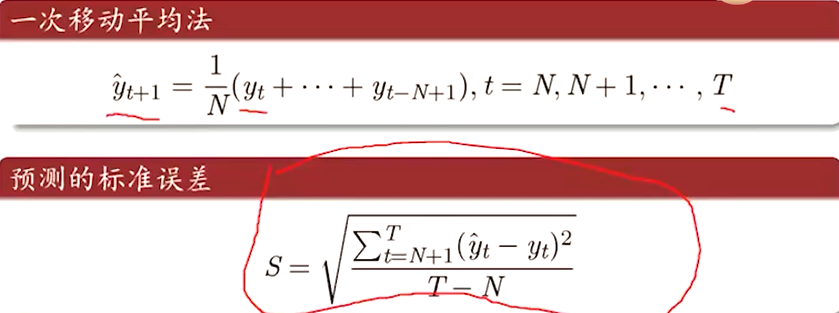

y=[533.8 574.6 606.9 649.8 705.1 772.0 816.4 892.7 963.9];
T=9;N=4;
c=cumsum(y);
%[(y1+...+y4)-0,(y1+...+y5)-y1,(y1+...+y6)-(y1+y2)]/n
yhat=(c(N:end)-[0 c(1:end-N)])/N;
y10=yhat(end)

y10 = 861.2500

S=norm(yhat(1:end-1)-y(N+1:end))/sqrt(T-N)

S = 143.0133

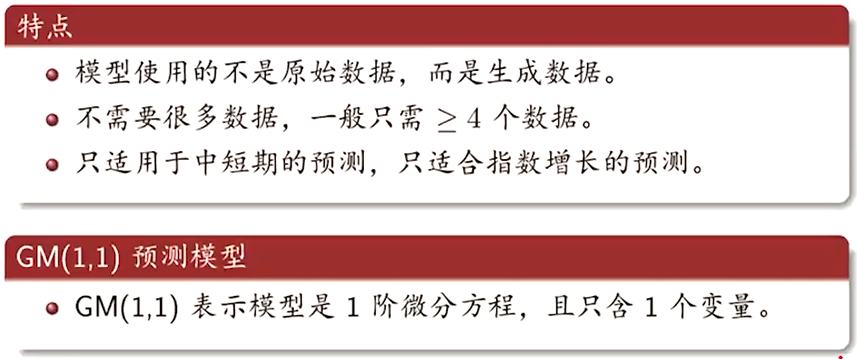

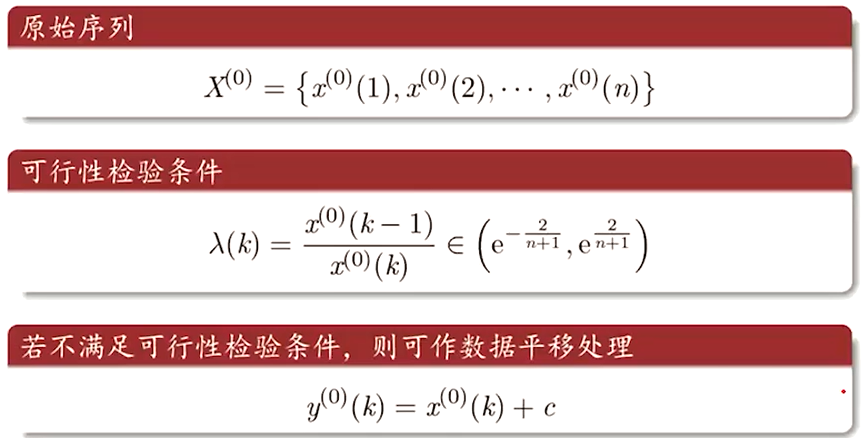

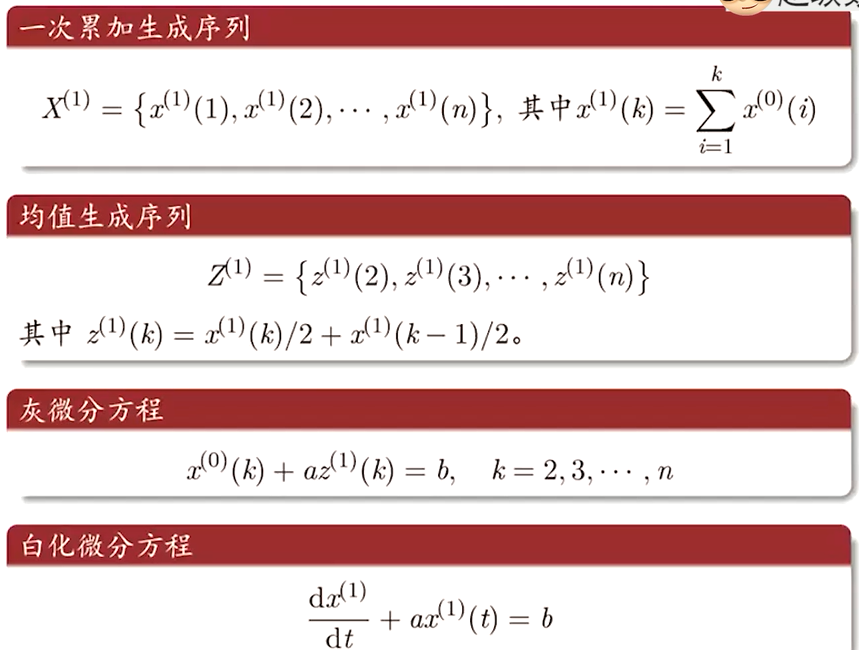

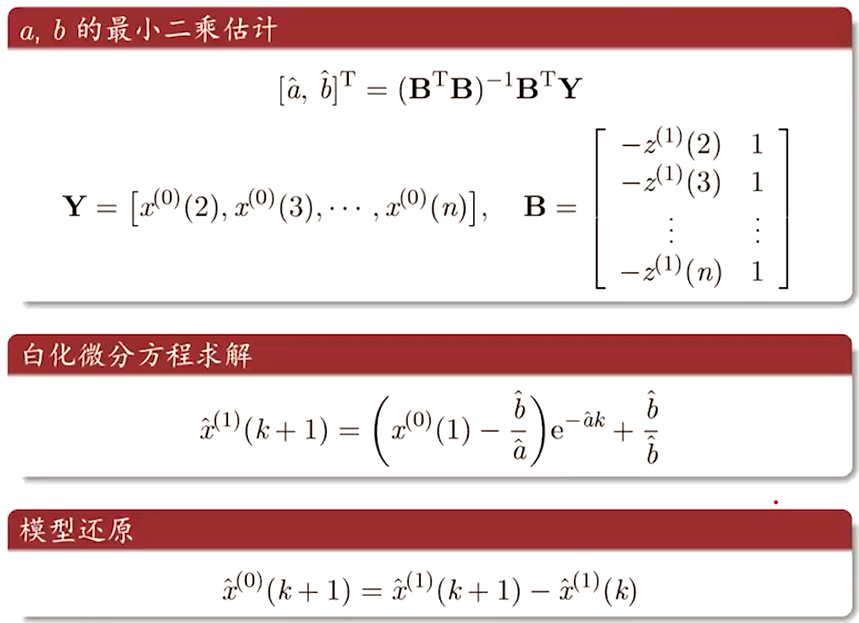

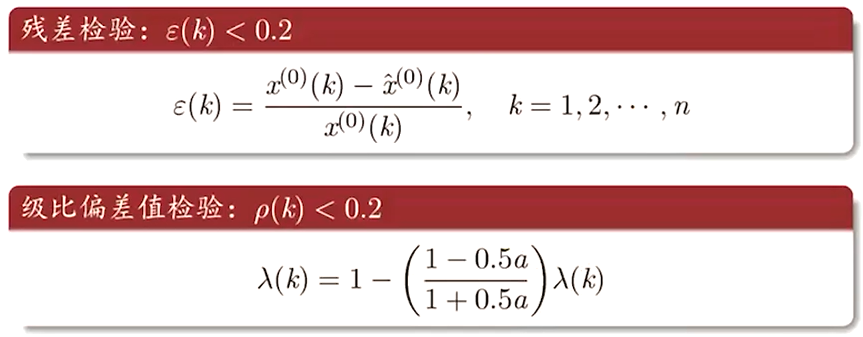

t0=[1999:2003]';
X0=[89;99;109;120;135];%原始序列
n=length(X0);
lambda=X0(1:n-1)./X0(2:n);
range=minmax(lambda')%检验

range =     0.8889    0.9083


exp([-2/(n+1),2/(n+2)])

ans =     0.7165    1.3307


X1=cumsum(X0);
Z1=(X1(1:n-1)+X1(2:n))/2;%均值
B=[-Z1,ones(n-1,1)];
Y=X0(2:n);
u=B\Y;a=u(1);b=u(2);
k=0:n+4;
xhat1=(X0(1)-b/a).*exp(-a*k)+b/a;
xhat0=[X0(1) diff(xhat1)]%还原

xhat0 =    89.0000   98.3326  109.0539  120.9440  134.1306  148.7549  164.9737  182.9609  202.9092  225.0325


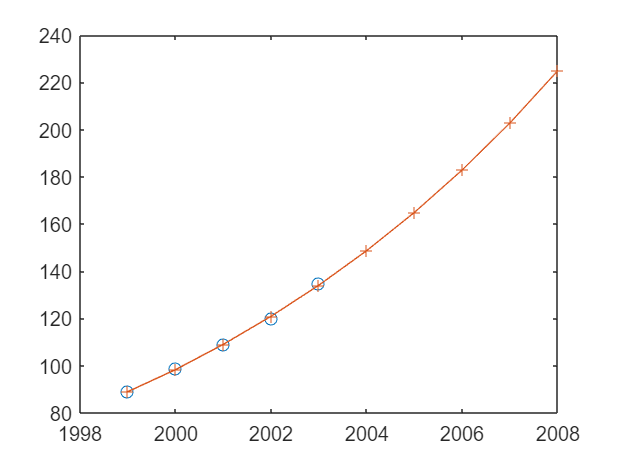

plot(t0,X0,'o',t0(1)+k,xhat0,'-+')

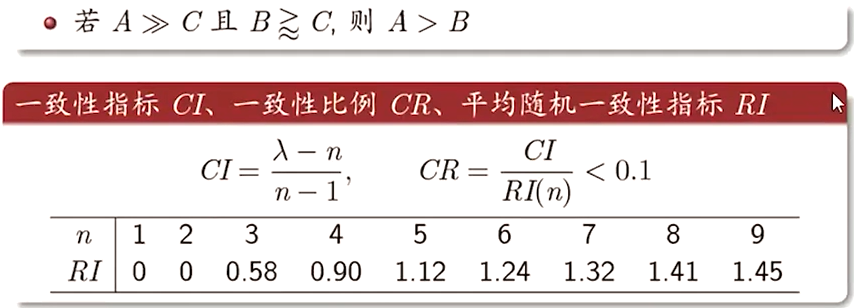

APH.m

A=[1/1 2/1 5/1 3/1
   1/2 1/1 3/1 1/2
   1/5 1/3 1/1 1/4
   1/3 2/1 4/1 1/1];
[V,D]=eig(A);
[lamda,i]=max(diag(D));
CI=(lambda-4)/(4-1);
CR=CI/0.9

CR =    -1.1485
   -1.1451
   -1.1451
   -1.1523


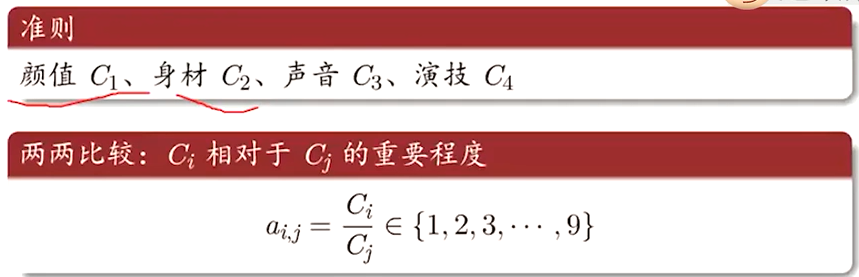

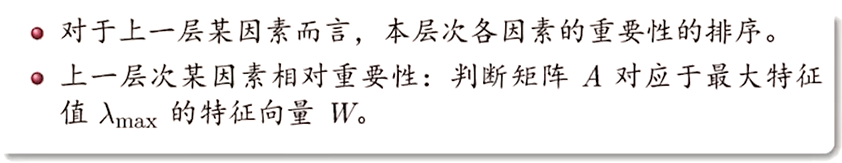

%判断矩阵
A=[1/1 2/1 5/1 3/1
   1/2 1/1 3/1 1/2
   1/5 1/3 1/1 1/4
   1/3 2/1 4/1 1/1];
[V,D]=eig(A);%求特征向量V,特征值D：A*V=V*D
[lambda,i]=max(diag(D));%最大特征值lambSda和其位置i
W=V(:,i);
w=W/sum(W)%归一化

w =     0.4816
    0.1864
    0.0713
    0.2608
